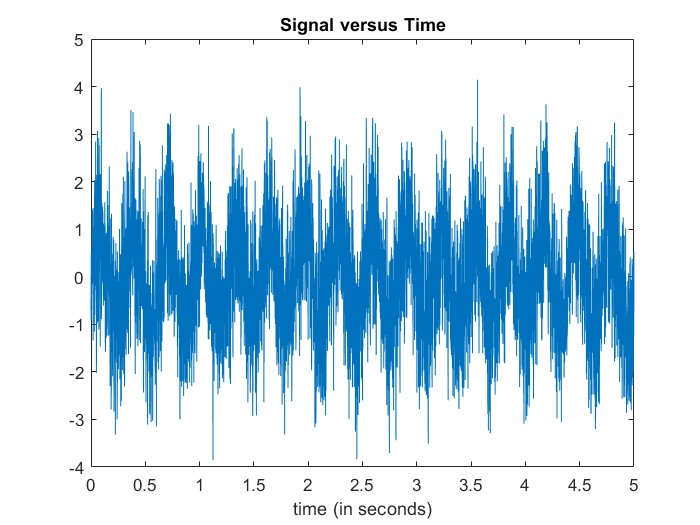

   clc;
   clear;
   
   Fs = 1000;                   % samples per second
   dt = 1/Fs;                   % seconds per sample
   StopTime = 5;             % seconds
   t = (0:dt:StopTime-dt);     % seconds
   %%Sine wave:
   Fc = 20;                     % hertz
   x = sin(Fc*t) + randn(size(t));
   % Plot the signal versus time:
   figure;
   plot(t,x);
   xlabel('time (in seconds)');
   title('Signal versus Time');

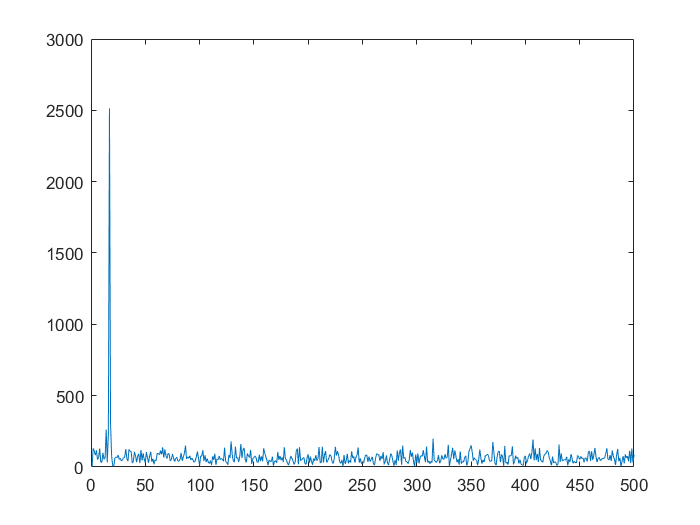


%detrended_AZ = abs(fft(x));
x = detrend(x);
detrended_AZ = fft(x);

plot(abs(detrended_AZ))
xlim([0 500])


size(detrended_AZ,2)

ans = 5000

f1 = 5

f1 = 5

f2 = 25

f2 = 25

f  = 0:size(abs(detrended_AZ),2)-1;
fc = 1/(2.*dt);

% freq = (f - f1)/(f2 -f1);
% cosine_part = 1-cos(pi.*freq);
% fc_above = -1./(2*pi.*(f.^2));

filtered_data = zeros(size(x));

for i = 1:size(f,2)
    if f(i) < f1
        
    elseif (f1 <= f(i)) && (f(i) <= f2)
        %filter_2 = 0.5.*cosine_part.*fc_above;
        
        freq = (f(i) - f1)/(f2 -f1);
        cosine_part = 1-cos(pi.*freq);
        fc_above = -1./(2*pi.*(f(i).^2));
        
        filter_2 = 0.5.*cosine_part;
        
        filtered_data(i) = detrended_AZ(i).*filter_2;
        i
        cosine_part
        
    elseif (f2 < f(i)) && (f(i) < fc)
        fc_above = -1./(2*pi.*(f(i).^2));
        
        filter_3 = fc_above;
        filtered_data(i) = detrended_AZ(i).*filter_3;
       
        %filter_3;
    end  
end

i = 6

cosine_part = 0

i = 7

cosine_part = 0.0123

i = 8

cosine_part = 0.0489

i = 9

cosine_part = 0.1090

i = 10

cosine_part = 0.1910

i = 11

cosine_part = 0.2929

i = 12

cosine_part = 0.4122

i = 13

cosine_part = 0.5460

i = 14

cosine_part = 0.6910

i = 15

cosine_part = 0.8436

i = 16

cosine_part = 1.0000

i = 17

cosine_part = 1.1564

i = 18

cosine_part = 1.3090

i = 19

cosine_part = 1.4540

i = 20

cosine_part = 1.5878

i = 21

cosine_part = 1.7071

i = 22

cosine_part = 1.8090

i = 23

cosine_part = 1.8910

i = 24

cosine_part = 1.9511

i = 25

cosine_part = 1.9877

i = 26

cosine_part = 2


filtered_data;

w = 2*pi.*Fc

w = 125.6637

z = (-1./(w.^2)).*filtered_data 

z =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0002 - 0.0000i  -0.0000 + 0.0001i   0.0001 + 0.0001i   0.0004 - 0.0008i   0.0002 - 0.0007i   0.0003 - 0.0010i  -0.0013 - 0.0056i   0.0004 + 0.0008i  -0.0015 - 0.0074i   0.0263 + 0.0882i   0.0026 + 0.0123i  -0.0024 + 0.0025i  -0.0002 + 0.0004i  -0.0000 + 0.0004i  -0.0036 - 0.0004i   0.0040 + 0.0014i   0.0035 + 0.0021i   0.0053 - 0.0005i  -0.0023 + 0.0025i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i



z_time = ifft(abs(z));

%plot(abs(z_time));

PSD = 2.*(abs(z)).^2

PSD =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0169    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



delta_f = f(2)-f(1)

delta_f = 1


size(z)

ans =            1        5000


% for j = 1:size(z,2)
%     m0 = m0 + PSD(j);
% end

m0 = sum(PSD)

m0 = 0.0176

m0 = delta_f*m0

m0 = 0.0176


hs = 4*sqrt(m0)

hs = 0.5313